% butterworth using IIR
clc
clear all
close all
order=4

order = 4

fc=100

fc = 100

f=50

f = 50

fs=1000

fs = 1000

[b,a]=butter(order,fc/(fs/2),'low')

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =    -0.4056    0.9762    1.5382    1.7177    2.6422    2.1158    1.7665    1.8918    0.9122    0.1840    0.1917   -0.3607   -1.4861   -1.7628   -1.8201   -1.1415   -1.2112   -1.4969   -1.7690   -0.5547   -0.2800    0.7694    1.6068    1.6296    1.8609    1.4524    2.3095    1.9310    1.0330   -0.0313    0.4613   -1.0674   -1.6859   -1.2055   -1.6043   -2.0174   -2.1592   -1.6457   -0.8666   -0.6270    0.5053    0.3983    0.9084    0.1015    2.2525    2.8287    1.5051    1.9971    1.5650    0.7487


subplot(2,1,1)
plot(t,sgnl)
filsgnl=filter(b,a,sgnl)

filsgnl =    -0.0020   -0.0078    0.0007    0.0759    0.2777    0.6299    1.0963    1.5825    1.9708    2.1638    2.1061    1.7996    1.3027    0.6954    0.0447   -0.5886   -1.1304   -1.5071   -1.6877   -1.7026   -1.6046   -1.4190   -1.1336   -0.7226   -0.1847    0.4297    1.0281    1.5220    1.8613    2.0196    1.9709    1.7066    1.2535    0.6609   -0.0023   -0.6457   -1.1898   -1.5960   -1.8544   -1.9534   -1.8748   -1.6102   -1.1792   -0.6433   -0.0932    0.4052    0.8517    1.2673    1.6319    1.8910


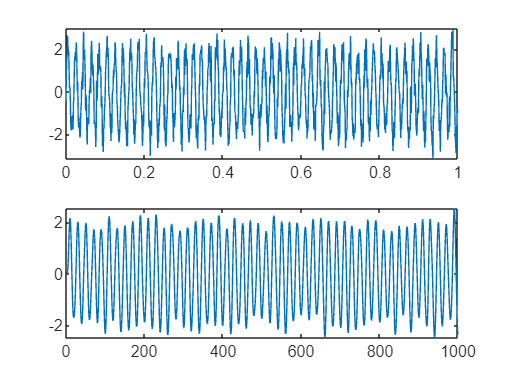

subplot(2,1,2)
plot(filsgnl)

%butterworth using FIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

order=30

order = 30

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.4740    0.9544    1.3065    2.2039    2.9852    2.6283    2.3421    1.7986    0.4054    0.5152   -0.6656   -0.9276   -0.8597   -0.7491   -3.1648   -2.5952   -1.7670   -0.4120   -2.2458   -0.6298   -0.0541    1.3722    1.3231    1.3040    1.1805    1.6289    2.5592    1.9746    1.0123   -0.1901    0.6705   -0.8623   -0.8786   -1.2994   -1.4170   -2.0227   -0.8719   -1.5805   -0.7353   -0.6138   -0.7706    0.2383    0.9862    1.8902    1.4364    2.0211    2.5556    1.3961    1.0640    0.6044


[b,a]=fir1(order,fc/(fs/2),'low',hamming(order+1))

b =     0.0000    0.0012    0.0028    0.0042    0.0039   -0.0000   -0.0083   -0.0186   -0.0254   -0.0212    0.0000    0.0396    0.0919    0.1451    0.1849    0.1997    0.1849    0.1451    0.0919    0.0396    0.0000   -0.0212   -0.0254   -0.0186   -0.0083   -0.0000    0.0039    0.0042    0.0028    0.0012    0.0000


a = 1

filsgnl=filter(b,a,sgnl)

filsgnl =     0.0000    0.0006    0.0025    0.0062    0.0122    0.0190    0.0220    0.0148   -0.0090   -0.0510   -0.1005   -0.1327   -0.1086    0.0153    0.2715    0.6610    1.1469    1.6536    2.0848    2.3450    2.3719    2.1479    1.7037    1.1037    0.4271   -0.2517   -0.8739   -1.3958   -1.7856   -2.0169   -2.0694   -1.9317   -1.6134   -1.1444   -0.5739    0.0386    0.6311    1.1507    1.5534    1.8070    1.8909    1.7950    1.5268    1.1131    0.6006    0.0461   -0.4869   -0.9431   -1.2849   -1.4960


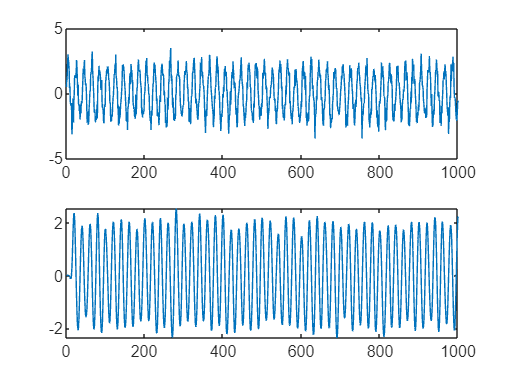

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

%chebyshev using IIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

order=40

order = 40

pb=0.5

pb = 0.5000

sb=40

sb = 40

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


[n,wn]=cheb1ord(fc/(fs/2),(fc+10)/(fs/2),pb,sb)

n = 14

wn = 0.2000

[b,a]=cheby1(n,pb,wn,'low')

b = 1.0e-07 *

    0.0003    0.0035    0.0228    0.0912    0.2509    0.5017    0.7526    0.8601    0.7526    0.5017    0.2509    0.0912    0.0228    0.0035    0.0003


a = 1.0e+03 *

    0.0010   -0.0120    0.0676   -0.2394    0.5924   -1.0836    1.5105   -1.6297    1.3673   -0.8877    0.4389   -0.1603    0.0409   -0.0065    0.0005


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.2451    0.2070    0.3741    1.4247    2.5770    2.5387    1.9656    1.8178    1.5619    0.5478   -0.2918   -0.6553   -0.5233   -1.2734   -1.5248   -2.2754   -1.2685   -2.0203   -1.6455   -0.7211   -0.7632    0.4956    1.0378    0.6393    1.6766    2.5796    1.4750    2.4064    0.7017    0.4532   -0.1332   -0.4456   -1.6234   -1.7679   -1.9949   -1.5414   -2.7885   -1.2149   -1.2840   -0.1656   -0.1499    0.3816    0.2687    2.8210    1.5330    2.9247    1.9310    1.5522    1.5690    0.5278


filsgnl=filter(b,a,sgnl)

filsgnl =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0010    0.0024    0.0055    0.0117    0.0236    0.0449    0.0809    0.1381    0.2240    0.3452    0.5055    0.7037    0.9306    1.1670    1.3838    1.5438    1.6065    1.5356    1.3069    0.9171    0.3883   -0.2302   -0.8676   -1.4411   -1.8698   -2.0903   -2.0680   -1.8053   -1.3405   -0.7404   -0.0875    0.5354    1.0587    1.4353    1.6428    1.6809    1.5635    1.3119    0.9483


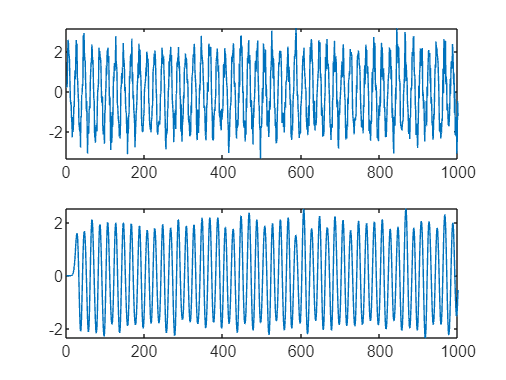

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

%chebyshev using FIR
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


order=60

order = 60

pb=0.5

pb = 0.5000

sb=40

sb = 40

sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =    -0.3568    0.1218    1.6217    1.1048    1.8196    2.1718    1.8595    1.9371    1.4305    0.6493   -0.5189   -0.0750   -1.0985   -0.7053   -1.8025   -1.6483   -1.2468   -2.2529   -0.5610   -1.1552    1.1134    0.1087    0.7215    1.3413    1.4086    1.7591    1.8805    1.1476    1.9275   -0.3399    0.1193   -0.2253   -2.2493   -1.4816   -2.3663   -1.7546   -1.9527   -1.4150   -1.3365   -0.9676    1.0753    0.8750   -0.2119    1.4679    1.8584    1.2930    1.8944    1.2792    1.8367    0.7347


coeff=fir1(order,fc/(fs/2),'low',chebwin(order+1,pb))

coeff =    -0.0000   -0.0066   -0.0110   -0.0114   -0.0074    0.0000    0.0080    0.0135    0.0141    0.0091   -0.0000   -0.0101   -0.0173   -0.0183   -0.0120    0.0000    0.0138    0.0240    0.0260    0.0175   -0.0000   -0.0214   -0.0391   -0.0446   -0.0322    0.0000    0.0483    0.1042    0.1564    0.1933    0.2066    0.1933    0.1564    0.1042    0.0483    0.0000   -0.0322   -0.0446   -0.0391   -0.0214   -0.0000    0.0175    0.0260    0.0240    0.0138    0.0000   -0.0120   -0.0183   -0.0173   -0.0101


filsgnl=filter(coeff,1,sgnl)

filsgnl =     0.0000    0.0023    0.0031   -0.0079   -0.0239   -0.0436   -0.0618   -0.0690   -0.0619   -0.0389   -0.0025    0.0415    0.0731    0.0850    0.0679    0.0329   -0.0087   -0.0430   -0.0479   -0.0284    0.0154    0.0539    0.0766    0.0654    0.0117   -0.0739   -0.1658   -0.2250   -0.2037   -0.0743    0.1908    0.5700    1.0162    1.4705    1.8433    2.0627    2.0700    1.8486    1.4173    0.8340    0.1781   -0.4752   -1.0423   -1.4533   -1.6869   -1.7404   -1.6253   -1.3736   -1.0131   -0.5789


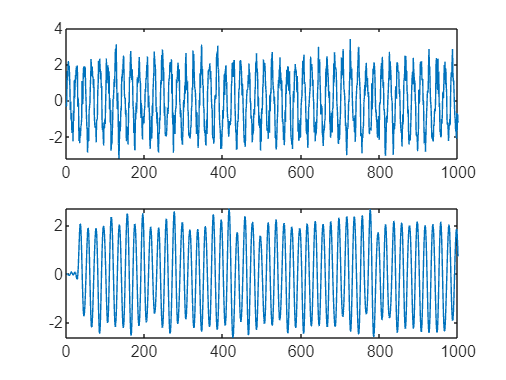

subplot(2,1,1)
plot(sgnl)
subplot(2,1,2)
plot(filsgnl)